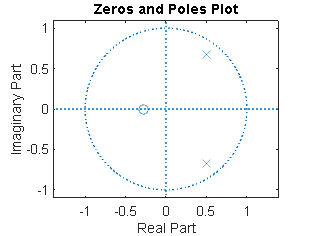

% TF to Zero and poles.
num = [1, 0.28];
den = [1, -1, 0.7];
[z, p, k] = tf2zp(num, den);

% Plot Zeros and Poles in the Complex Plane
zplane(z, p);
title('Zeros and Poles Plot');

%Zero and poles to TF

z =-0.28;
p = [
  0.5+ 0.6708i,
  0.5- 0.6708i,
];
k = 1;

[num,den] = zp2tf(z,p,k)

num =          0    1.0000    0.2800


den =     1.0000   -1.0000    0.7000


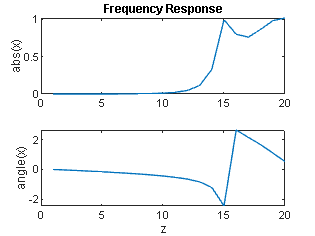

% Frequency response 
num = [0.008, -0.033, 0.05, -0.033, 0.008];
den = [1, 2.37, 2.7, 1.6, 0.4];
w = 20;
x = freqz(num,den,w);
subplot(211);
plot(abs(x));
title('Frequency Response')
ylabel('abs(x)')
subplot(212);

plot(angle(x));
ylabel('angle(x)')
xlabel('z')